2a.

clear all
close all
path = "C:\Users\atche\Source\repos\OpenCVCourse\OpenCVCourse\Resources\IMG-7763-Warped.jpg"

path = "C:\Users\atche\Source\repos\OpenCVCourse\OpenCVCourse\Resources\IMG-7763-Warped.jpg"

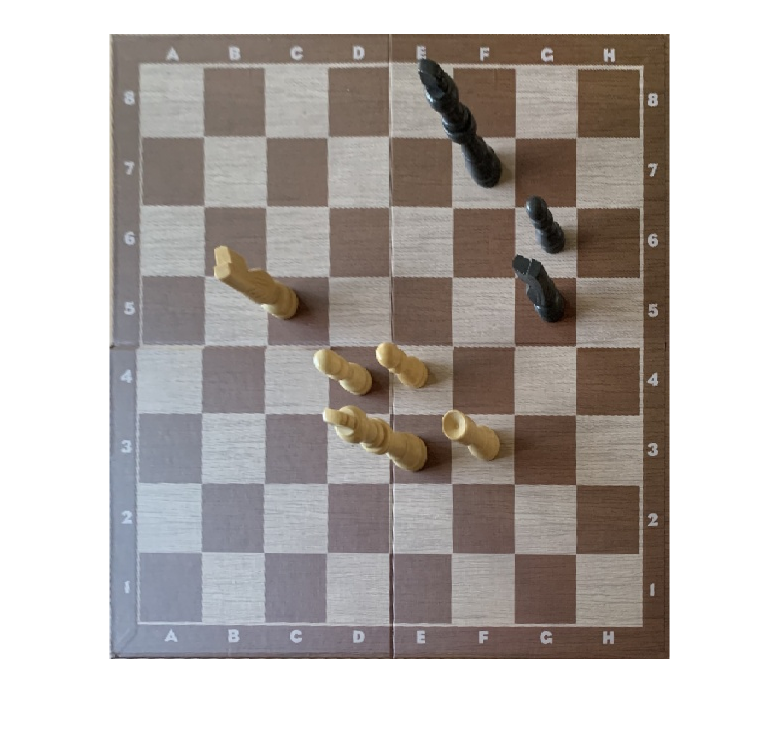

I = imread(path);
imshow(path)

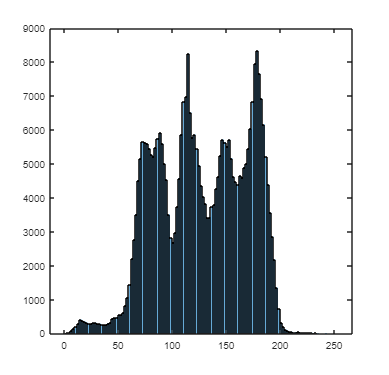

I_gray = rgb2gray(I);
%imshow(I_gray)
I_contrast = imadjust(I_gray);
%imshow(I_contrast)
histogram(I_gray)

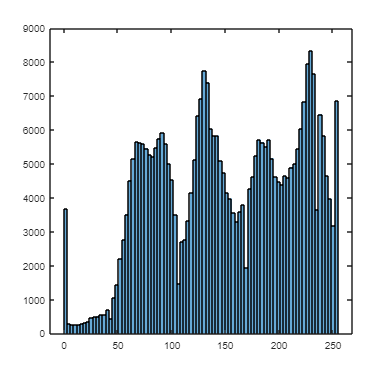

histogram(I_contrast)

High contrast images have more values in the extreme ranges for the color intensity. There are more images in the 0 and 255 range.

Low contrast images have more uniformly spread out not just in the extreme ranges. The standard deviation is less for low contrast images.

2b. 

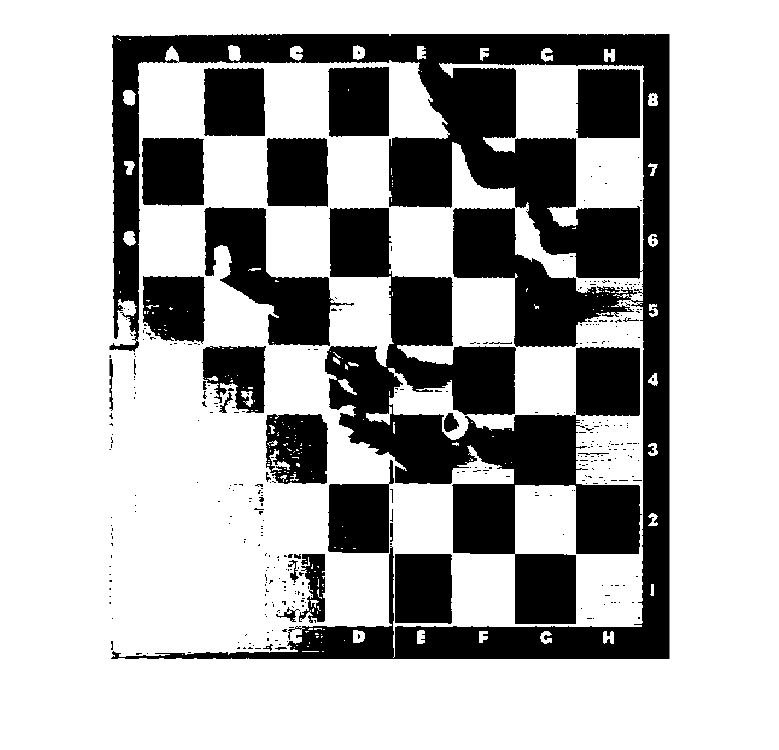

I_bin = imbinarize(I_gray);
imshow(I_bin)

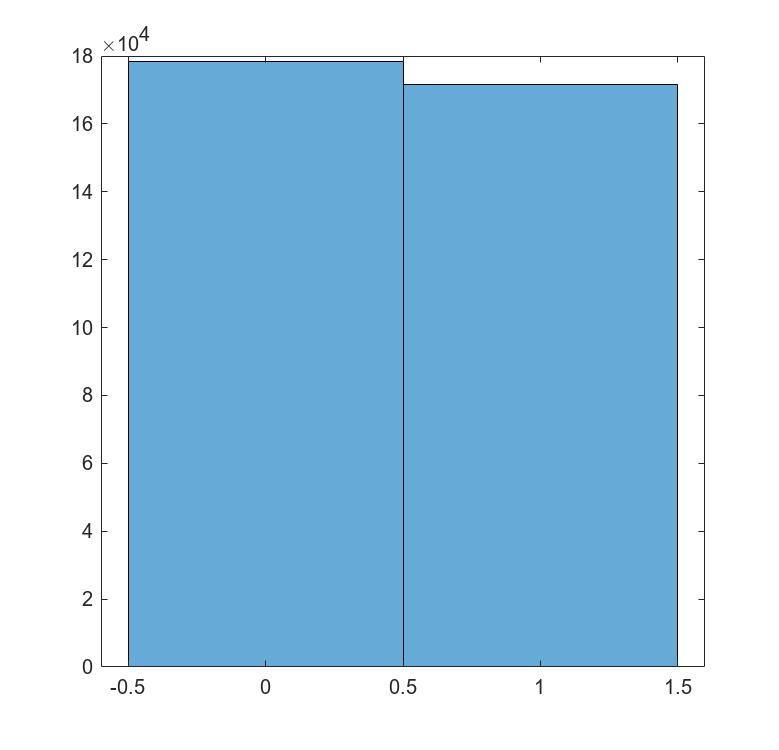

histogram(I_bin)

Binary images have only two values 0/1 where each pixel is either black or white. 

2c. 

i.

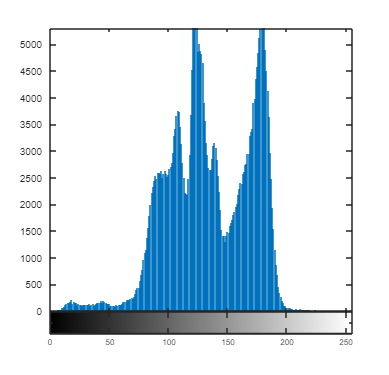

%I = imresize(I,0.25)
I_red = I(:,:,1);
%imshow(I_red)
I_green = I(:,:,2);
%imshow(I_green)
I_blue = I(:,:,3);
%imshow(I_blue)

imhist(I_red)

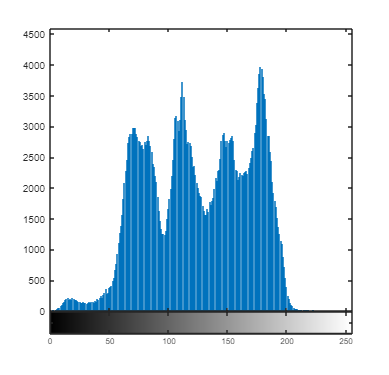

imhist(I_green)

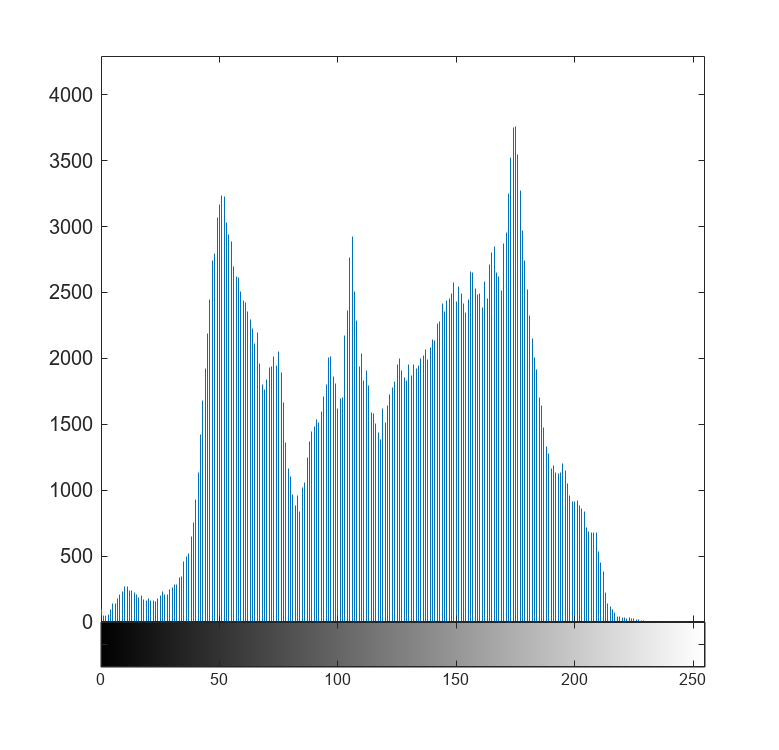

imhist(I_blue)

ii.

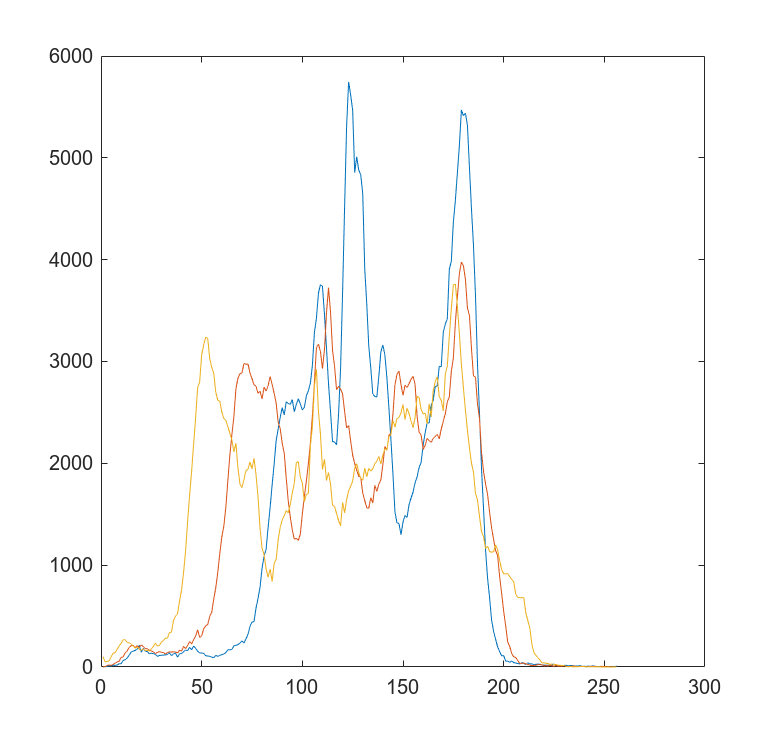


h_one = imhist(I_red);
h_two = imhist(I_green);
h_three = imhist(I_blue);

h_conc = [h_one, h_two, h_three];

plot(h_conc)

iii. 

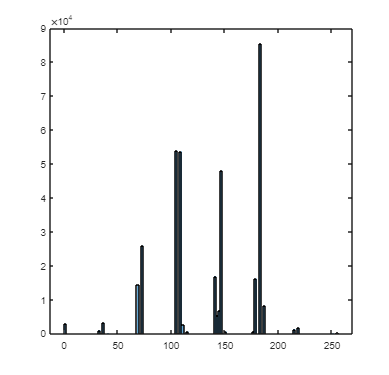

%Get 3 MSB from Red channel

%iterate through 3 channels
I_res = size(I);
imageNew = zeros(I_res(1),I_res(2),1);

for x = 1:I_res(1) %num rows or height
    for y = 1:I_res(2) %num cols or width //start at height 1
       red_msb = bitand(I_red(x,y),224);
       green_msb = bitshift(bitand(I_green(x,y),224),-3);
       blue_msb = bitshift(I_blue(x,y),-6);
       imageNew(x,y) = bitor(bitor(red_msb,green_msb),blue_msb);
    end    
end
histogram(imageNew)

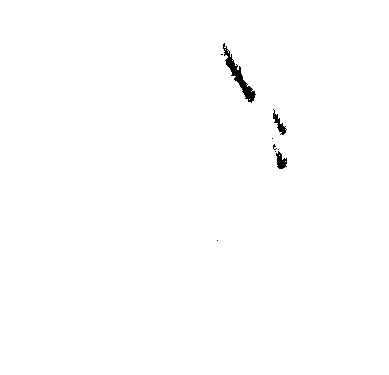

imshow(imageNew) %validated last ten and first ten pixel values 

2d.

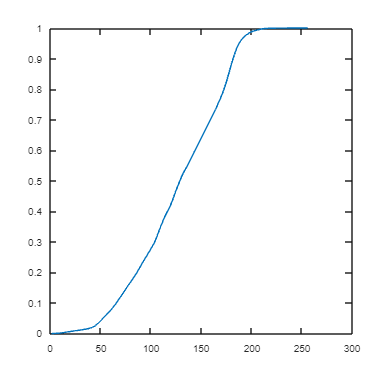

[count, binLocations] = imhist(I);
pdf = count/sum(count);
cdf = cumsum(pdf);
plot(cdf)

2e.

I_mean = mean2(I)

I_mean = 126.9391

I_var = sqrt(std2(I))

I_var = 6.6188

I_med = median(I,'all')

I_med = uint8
128

The mean is `126.9391`

`The variance is 6.6188`

`The median is 128`